# LAB SESSION 1: INTRODUCTION TO SIGNAL PROCESSING

## Biomedical Signals

#### **Student Names:**** Marta Maldonado and Marcos Oriol**

clc; clear;

fs = 100; % Hz

## 1. Template Matching

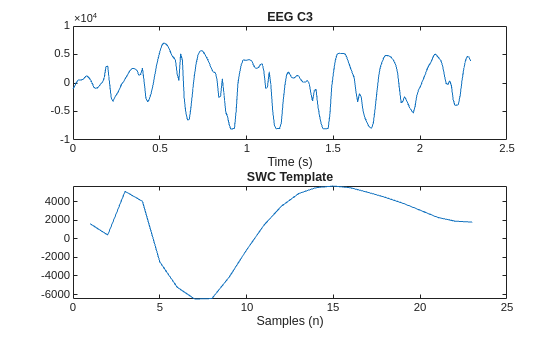

channel = 'c3';
channel_dat_filename = strcat('eeg2-', channel, '.dat'); 
channel_dat_file_path = strcat('matched_filter/', channel_dat_filename);

channel_c3_data = load(channel_dat_file_path)';
time = 0:1/fs:(length(channel_c3_data)-1)/fs;
template = channel_c3_data(0.61*fs:0.83*fs);

figure;
subplot(2,1,1);
plot(time, channel_c3_data);
title('EEG C3');
xlabel('Time (s)')
subplot(2,1,2);
plot(template);
title('SWC Template');
xlabel('Samples (n)');

**1.2. Normalized Cross-Correlation**

Once we have calculated the pattern of the representative ectopic ECG beat, we now need to:

- Apply 'xcorr' between the ECG signal and the representative ectopic beat, to compute their similarity at each lag.

- Normalization.

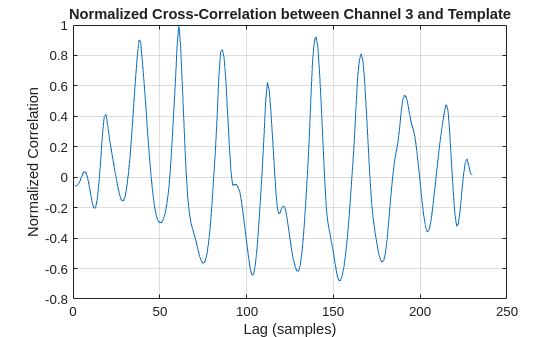

% Cross-correlation between 'ecgpvc' and 'representative_beat'
[corr, lags] = xcorr(channel_c3_data, template);
% Since the full cross-correlation is symmetric, we keep the positive lags
trimmed_corr = corr(lags >= 0);

% Normalization
normalized_trim_corr = trimmed_corr / max(trimmed_corr);

figure;
plot(normalized_trim_corr);
title('Normalized Cross-Correlation between Channel 3 and Template');
xlabel('Lag (samples)');
ylabel('Normalized Correlation');
grid on;

**1.3. Apply a threshold**

- *findpeaks:*

### *C3*

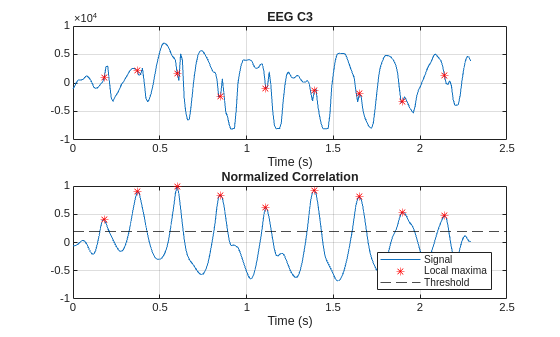

% Apply a threshold
threshold = 0.2; 

% Find indxs above the threshold
[~, idxs] = findpeaks(normalized_trim_corr, "MinPeakHeight", threshold);

% Plot the detected ectopic beats
plot_local_max(channel_c3_data, normalized_trim_corr, time, idxs, threshold);

### C4

### IIR Reverse template

reversed_template = fliplr(template);

figure;
subplot(2,1,1);
plot(template);
title('Template');

subplot(2,1,2);
plot(reversed_template);
title('Reverse Template');

### Filter the signal

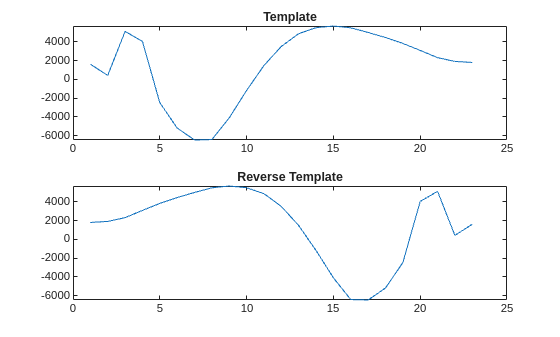

filtered_c3 = filter(channel_c3_data);